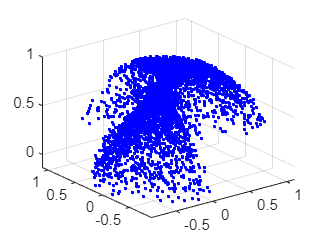



% The range of the motion for the 4 joint parameters t1, t2, t3, t4 are 

t1 = -155+(rand(5000,1)*155)*(pi/180);

t2 = -15+(rand(5000,1)*120)*(pi/180); 

t3 = 15+(rand(5000,1)*145)*(pi/180); 

t4 = -350+(rand(5000,1)*350)*(pi/180);


% From the transformation matrix 

x = vpa("0.22").*cos(t1) + vpa("0.85").*cos(t1).*cos(t2) - vpa("0.85").*cos(t1).*sin(t2).*sin(t3) + vpa("0.85").*cos(t1).*cos(t2).*cos(t3);

y = vpa("0.22").*sin(t1) + vpa("0.85").*cos(t2).*sin(t1) - vpa("0.85").*sin(t1).*sin(t2).*sin(t3) + vpa("0.85").*cos(t2).*cos(t3).*sin(t1);

z = vpa("0.85").*sin(t2) + vpa("0.85").*cos(t3).*sin(t2)  + vpa("0.85").*sin(t2).*sin(t3) + vpa("0.62");


% Generating the robot workspace using the scatter plot

scatter3(x,y,z, '.', 'blue')

grid on